# Homework #2

Author: Victoria Subritzky Katz

Date: 09/08/2023

## Q1 

The paper I looked at was "Investigating Cognitive Neuroscience Theories of Human Intelligence: A Connectome-Based Predictive Modeling Approach" by Evan Anderson & Aron Barbey. Specifically I looked at the table 1 where they reported the distribution of the results of a series of cognitive tests performed by a sample of the population (N=297). I chose to simulate the data distribution for the results of the Law School Admissions Test. 

Paper link: https://onlinelibrary.wiley.com/doi/10.1002/hbm.26164

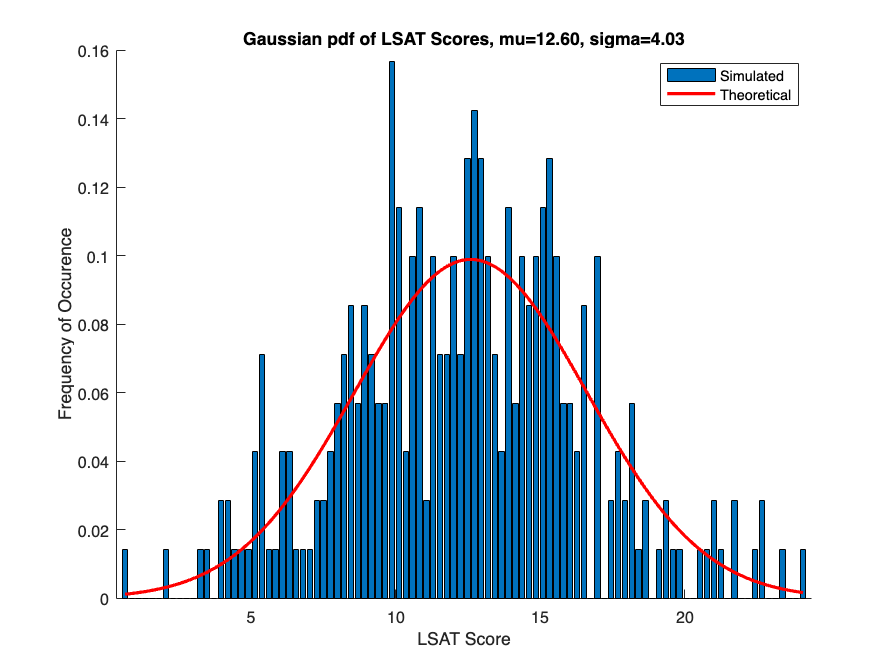




%% Normal (Gaussian) distribution
%
% Python: https://github.com/PennNGG/Quantitative-Neuroscience/blob/master/Probability%20Distributions/Python/Gaussian%20(Normal).ipynb
%
% This is another CONTINOUS distribution that describes the relative 
%  frequencies of occurrence of continuous values following a bell-shaped
%  curve.
%  
% Let's compare simulated and theoretical Gaussians
mu = 12.6;
sigma = 4.03;
N = 297;

% Get samples
samples = normrnd(mu, sigma, N, 1);

% plot histogram, pick number of bins
cla reset; hold on;
nbins = 100;
[counts, edges] = histcounts(samples, nbins);
xaxis = edges(1:end-1)+diff(edges);
npdf = counts./trapz(xaxis, counts);
bar(xaxis, npdf);

% Show theoretical pdf in red
plot(xaxis, normpdf(xaxis, mu, sigma), 'r-', 'LineWidth', 2);

% labels, ets
title(sprintf('Gaussian pdf of LSAT Scores, mu=%.2f, sigma=%.2f', mu, sigma))
xlabel('LSAT Score');
ylabel('Frequency of Occurence');
legend('Simulated', 'Theoretical')


% Some summary statistics
% 1. The sample mean
disp(mean(samples))

   12.2499




% 2. The expected value of the empirical distribution: the sum of 
%     probability x value per bin. This should be similar to the sample 
%     mean, but recognize that we lost some information from the binning
%     (i.e., use more bins and this should get closer to the sample mean)
disp(sum(xaxis.*diff(edges).*npdf))

   12.4147




% 3. The expected value of the theoretical distribution
disp(sum(xaxis.*diff(edges).*normpdf(xaxis, mu, sigma)))

   12.5509




% Now standardize ("z-score") the samples by subtracting the mean and 
%  dividing by the STD
% The harder way
zSamples = (samples-mean(samples))./std(samples);

% The easier way
z2Samples = zscore(samples);

% Check that they are the same
disp(unique(zSamples-z2Samples))

     0



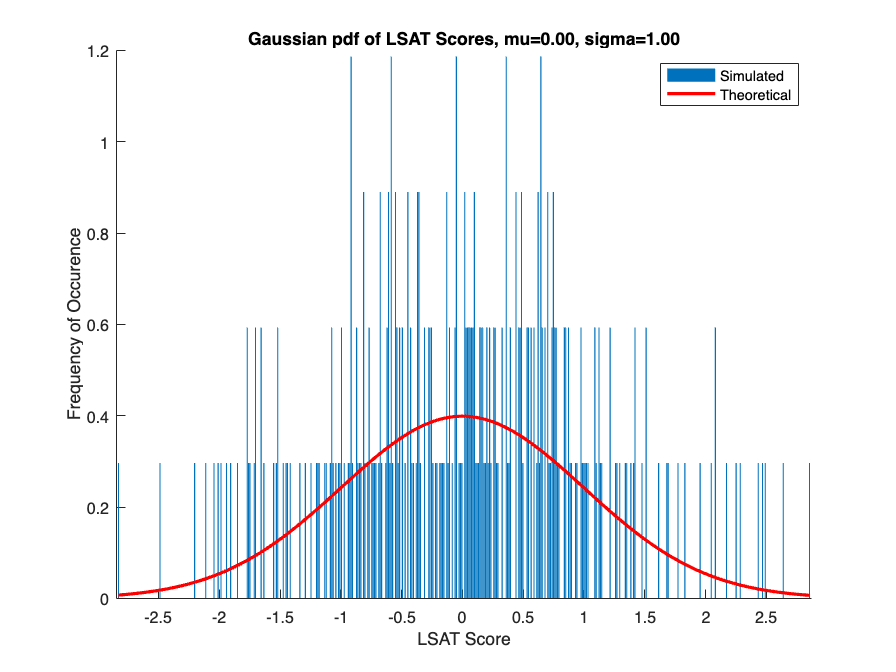


% Show the distribution of z-scored values
cla reset; hold on;
nbins = 500;
[counts, edges] = histcounts(zSamples, nbins);
xaxis = edges(1:end-1)+diff(edges);
npdf = counts./trapz(xaxis, counts);
bar(xaxis, npdf);

% This is the "standard normal" pdf with mean=0, std=var=1
npdf = normpdf(xaxis);
plot(xaxis, npdf, 'r-', 'LineWidth', 2);

% labels, ets
title(sprintf('Gaussian pdf of LSAT Scores, mu=%.2f, sigma=%.2f', ...
   mean(zSamples), std(zSamples)))
xlabel('LSAT Score');
ylabel('Frequency of Occurence');
legend('Simulated', 'Theoretical')


%%%
%
% How much of the distribution is within 1,2,3+ standard deviations (also
% called z-scores)? Here it's easy to tell after we standardized the
% distribution
stds = (1:6)';

% Will compute in several ways (here we are just preallocating arrays to 
%  store the data, the columns are the different calculations): 
%  1. From the sampled distribution
%  2. From the (sampled) theoretical distribution
%  3. From the real theoretical distribution
pcts = zeros(length(stds), 3);

% Loop through and compute for each std
for ss = 1:length(stds)
   
   % 1. From the sampled distribution (compute as pct)
   pcts(ss,1) = 100.*sum(abs(zSamples) <= stds(ss))./length(zSamples);
   
   %  2. From the (sampled) theoretical distribution using trapz
   Lz = xaxis>=-stds(ss) & xaxis<=stds(ss); % Logical array to take only samples within given std
   pcts(ss, 2) = 100.*trapz(xaxis(Lz), npdf(Lz));
   
   %  3. From the real theoretical distribution: use the Gaussian 
   %     cumulative probability density function at z (i.e., at the 
   %     given std in the standardized normal). So 1-cdf is the integral 
   %     of the tail. We want the integral of the pdf minus the integral 
   %     of both tails:
   pcts(ss, 3) = 100.*(1-2.*(1-normcdf(stds(ss))));
end

% Show all
disp([stds pcts])

    1.0000   71.0438   68.1047   68.2689
    2.0000   94.2761   95.3762   95.4500
    3.0000  100.0000   99.5510   99.7300
    4.0000  100.0000   99.5510   99.9937
    5.0000  100.0000   99.5510   99.9999
    6.0000  100.0000   99.5510  100.0000




%%%
%
% Some other useful properties of Gaussians

% Get samples
mu = 5;
sigma = 10;
N = 10000;
samples = normrnd(mu, sigma, N, 1);

fprintf('mean=%.2f, std=%.2f, var=%.2f\n', ...
   mean(samples), std(samples), var(samples))

mean=5.00, std=9.98, var=99.64



% 1. Add a constant changes the mean, not the std
offset = 20;
fprintf('mean=%.2f, std=%.2f, var=%.2f\n', ...
   mean(samples+offset), std(samples+offset), var(samples+offset))

mean=25.00, std=9.98, var=99.64



% 2. Multiply by a constant scales the mean by that amount, the variance by
%     that amount squared
scale = 7;
fprintf('mean=%.2f, std=%.2f, var=%.2f\n', ...
   mean(samples*scale), std(samples*scale), var(samples*scale))

mean=35.00, std=69.88, var=4882.56



% 3. Adding two Gaussian random variables gives you a gaussian random 
%     variable with:
%        mean = sum of the two means
%        variance = sum of the two variances
mu2 = 5;
sigma2 = 10;

samples2 = normrnd(mu2, sigma2, N, 1);
fprintf('mean2=%.2f, std2=%.2f, var2=%.2f\n', ...
   mean(samples+samples2), std(samples+samples2), var(samples+samples2))

mean2=9.90, std2=14.36, var2=206.09
